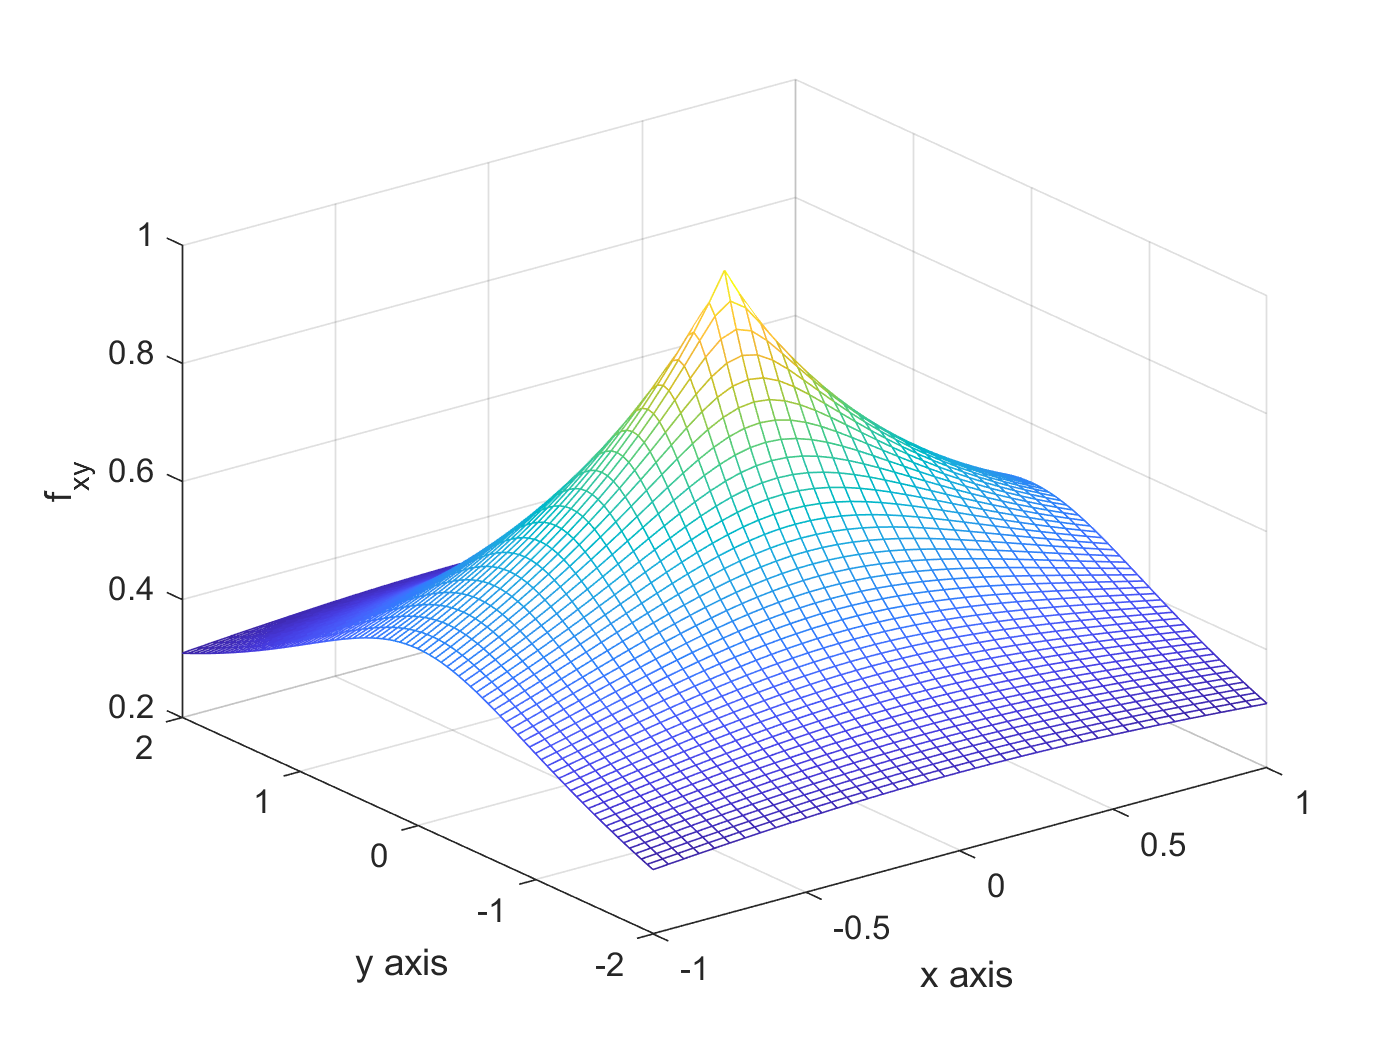

% Author: Shi Jie (Barney) Wei
% Date: 01/14/19

% 1) Define the variables x, y
x = linspace(-1, 1, 41);
y = linspace(-2, 2, 81);
% 2) Verify sizes of the vectors x, y are 1x41 and 1x81, respectively
[nr, nc] = size(x);    % % of rows and cols
length(x);             % # of cols
% 3) Calculate matrices used to 3-D plot
[X, Y] = meshgrid(x, y);
fxy = 1 ./ (1 + (X.^2 + Y.^2).^0.5);
% 4) Generate 3D plot of this charge distribution
figure;
mesh(X, Y, fxy);
xlabel('x axis');
ylabel('y axis');
zlabel('f_{xy}');

% 5) Create 2D plot that shows the variation of f(x,y) with respect to x
%    5.a) y =  -2 [m]
[r, a] = find(y==-2);
%    5.b) y =   0 [m]
[r, b] = find(y==0);
%    5.c) y = 1.6 [m]
[r, c] = find(y==1.6);
%    5.d) Plot
figure;
hold;

Current plot held


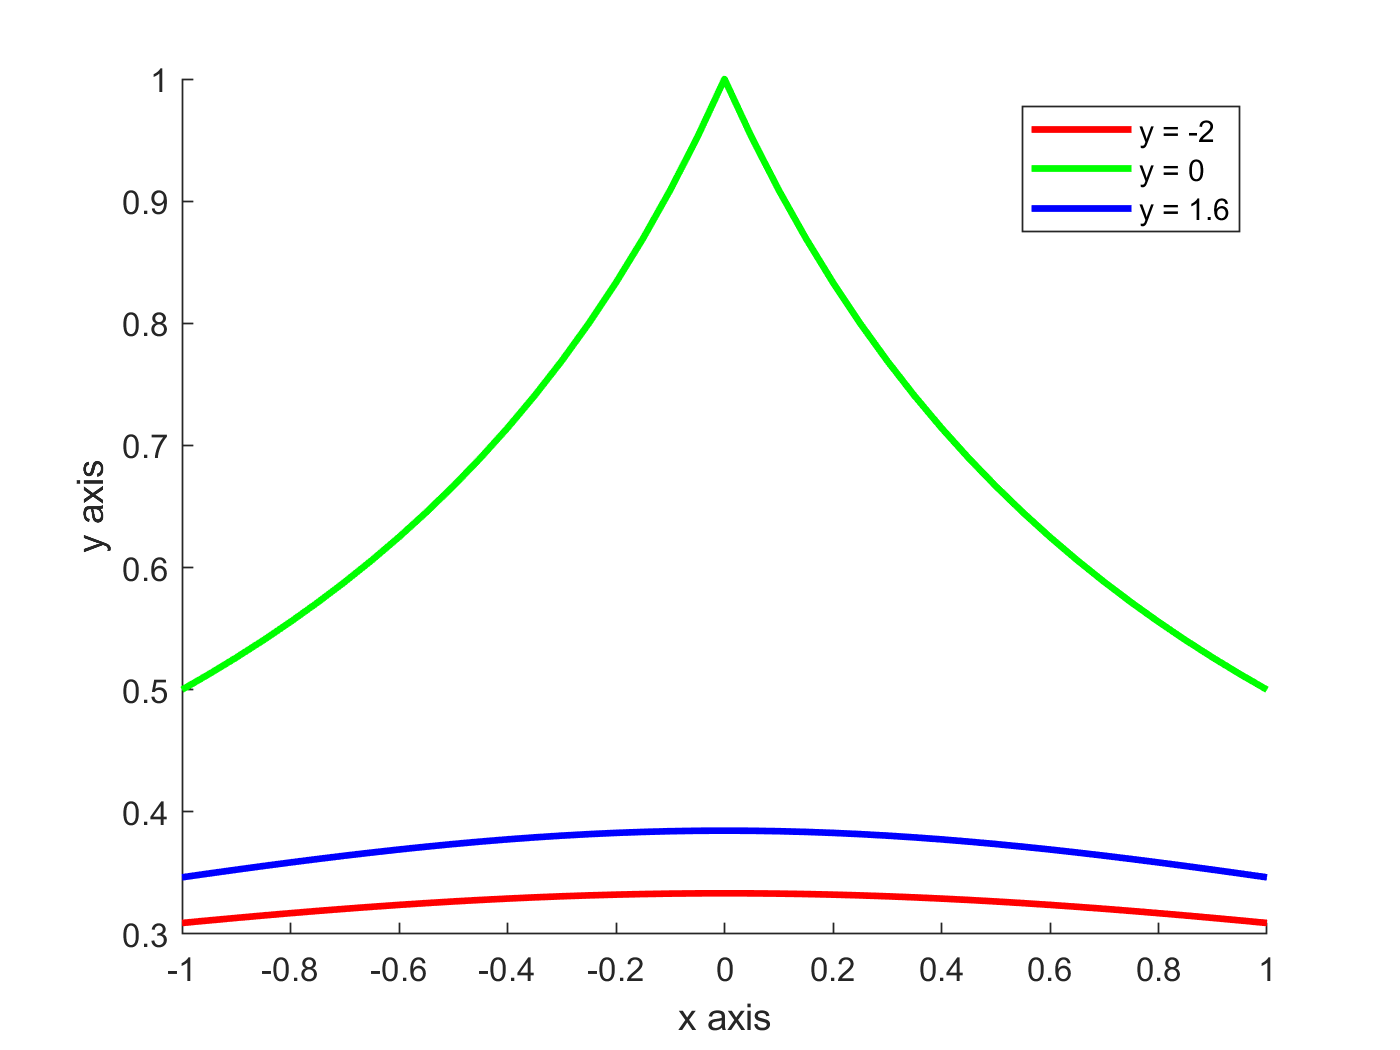

plot(x, fxy(a, :), 'r-', 'LineWidth', 2);
plot(x, fxy(b, :), 'g-', 'LineWidth', 2);
plot(x, fxy(c, :), 'b-', 'LineWidth', 2);
xlabel('x axis');
ylabel('y axis');
legend('y = -2', 'y = 0', 'y = 1.6')